% чтение
arr_st = imread("eule.jpg") 

arr_st = 1024×1024×3 uint8 array
arr_st(:,:,1) =

    40    41    42    42    42    42    41    40    41    41    42    42    42    42    43    43    41    42    43    43    44    44    43    43    44    44    45    45    45    45    46    46    45    45    45    45    45    45    45    45    45    45    45    45    45    45    45    45    46    46    45    45    45    45    46    46    45    45    45    45    45    45    45    45    48    47    46    45    45    46    47    48    47    47    47    47    47    47    47    47    47    47    47    47    47    47    47    47    48    48    48    48    48    48    48    48    47    47    48    48    48    48    49    49    47    48    50    49    48    48    49    51    49    50    51    51    51    51    50    49    50    50    50    50    50    51    51    51    52    52    52    51    51    50    50    50    51    51    51    52    52    52    52    52    52    52    52    52    53    53    53    53    53    53    53    53    53    53  



% zu weiss und schwartz
w_s_im = im2gray(arr_st)

w_s_im = 1024×1024 uint8 matrix
   54   55   56   56   56   56   55   54   55   55   56   56   56   56   57   57   55   56   57   57   58   58   57   57   58   58   59   59   59   59   60   60   59   59   59   59   59   59   59   59   59   59   59   59   59   59   59   59   60   60
   54   55   56   56   56   56   55   54   55   55   56   56   56   56   57   57   56   56   57   58   58   58   58   57   58   58   58   59   59   59   59   60   59   59   59   59   59   59   59   59   59   59   59   59   59   59   59   59   60   60
   55   55   56   56   56   56   55   55   55   55   56   56   56   56   57   57   56   57   58   58   59   58   58   58   58   58   58   59   59   59   59   59   59   59   59   59   59   59   59   59   59   59   59   59   59   59   59   59   60   60
   55   55   55   55   55   55   55   55   55   55   56   56   56   56   57   57   57   57   58   59   59   59   58   58   58   58   58   58   59   59   59   59   59   59   59   59   59   59   59   59   59   59   59



n_1 = 5

n_1 = 5

n_2 = 9

n_2 = 9

n_3 = 13

n_3 = 13


% block-Unschärfe-Kern
bkern_1 = ones(n_1) / n_1^2

bkern_1 =     0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400


bkern_2 = ones(n_2) / n_2^2

bkern_2 =     0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123


bkern_3 = ones(n_3) / n_3^2

bkern_3 =     0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059
    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059
    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059
    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059
    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059
    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059
    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059
    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059    0.0059   


% Gauss-Unscharfe_Kern
gkern_1 = zeros(n_1, n_1)

gkern_1 =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


gkern_2 = zeros(n_2, n_2)

gkern_2 =      0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0


gkern_3 = zeros(n_3, n_3)

gkern_3 =      0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0



% Gauss arbeit 1

s1 = 0

s1 = 0


for i = 1 : n_1
    for j = 1 : n_1
        gkern_1(i, j) = exp(-9 / n_1^2 * ((i - (n_1 + 1) / 2)^2 + (j - (n_1 + 1) / 2)^2))
        s1 = s1 + gkern_1(i, j)
    end
end

gkern_1 =     0.0561         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


s1 = 0.0561

gkern_1 =     0.0561    0.1653         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


s1 = 0.2214

gkern_1 =     0.0561    0.1653    0.2369         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


s1 = 0.4584

gkern_1 =     0.0561    0.1653    0.2369    0.1653         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


s1 = 0.6237

gkern_1 =     0.0561    0.1653    0.2369    0.1653    0.0561
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


s1 = 0.6798

gkern_1 =     0.0561    0.1653    0.2369    0.1653    0.0561
    0.1653         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


s1 = 0.8451

gkern_1 =     0.0561    0.1653    0.2369    0.1653    0.0561
    0.1653    0.4868         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


s1 = 1.3318

gkern_1 =     0.0561    0.1653    0.2369    0.1653    0.0561
    0.1653    0.4868    0.6977         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


s1 = 2.0295

gkern_1 =     0.0561    0.1653    0.2369    0.1653    0.0561
    0.1653    0.4868    0.6977    0.4868         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


s1 = 2.5163

gkern_1 =     0.0561    0.1653    0.2369    0.1653    0.0561
    0.1653    0.4868    0.6977    0.4868    0.1653
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


s1 = 2.6816

gkern_1 =     0.0561    0.1653    0.2369    0.1653    0.0561
    0.1653    0.4868    0.6977    0.4868    0.1653
    0.2369         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


s1 = 2.9185

gkern_1 =     0.0561    0.1653    0.2369    0.1653    0.0561
    0.1653    0.4868    0.6977    0.4868    0.1653
    0.2369    0.6977         0         0         0
         0         0         0         0         0
         0         0         0         0         0


s1 = 3.6162

gkern_1 =     0.0561    0.1653    0.2369    0.1653    0.0561
    0.1653    0.4868    0.6977    0.4868    0.1653
    0.2369    0.6977    1.0000         0         0
         0         0         0         0         0
         0         0         0         0         0


s1 = 4.6162

gkern_1 =     0.0561    0.1653    0.2369    0.1653    0.0561
    0.1653    0.4868    0.6977    0.4868    0.1653
    0.2369    0.6977    1.0000    0.6977         0
         0         0         0         0         0
         0         0         0         0         0


s1 = 5.3139

gkern_1 =     0.0561    0.1653    0.2369    0.1653    0.0561
    0.1653    0.4868    0.6977    0.4868    0.1653
    0.2369    0.6977    1.0000    0.6977    0.2369
         0         0         0         0         0
         0         0         0         0         0


s1 = 5.5508

gkern_1 =     0.0561    0.1653    0.2369    0.1653    0.0561
    0.1653    0.4868    0.6977    0.4868    0.1653
    0.2369    0.6977    1.0000    0.6977    0.2369
    0.1653         0         0         0         0
         0         0         0         0         0


s1 = 5.7161

gkern_1 =     0.0561    0.1653    0.2369    0.1653    0.0561
    0.1653    0.4868    0.6977    0.4868    0.1653
    0.2369    0.6977    1.0000    0.6977    0.2369
    0.1653    0.4868         0         0         0
         0         0         0         0         0


s1 = 6.2028

gkern_1 =     0.0561    0.1653    0.2369    0.1653    0.0561
    0.1653    0.4868    0.6977    0.4868    0.1653
    0.2369    0.6977    1.0000    0.6977    0.2369
    0.1653    0.4868    0.6977         0         0
         0         0         0         0         0


s1 = 6.9005

gkern_1 =     0.0561    0.1653    0.2369    0.1653    0.0561
    0.1653    0.4868    0.6977    0.4868    0.1653
    0.2369    0.6977    1.0000    0.6977    0.2369
    0.1653    0.4868    0.6977    0.4868         0
         0         0         0         0         0


s1 = 7.3873

gkern_1 =     0.0561    0.1653    0.2369    0.1653    0.0561
    0.1653    0.4868    0.6977    0.4868    0.1653
    0.2369    0.6977    1.0000    0.6977    0.2369
    0.1653    0.4868    0.6977    0.4868    0.1653
         0         0         0         0         0


s1 = 7.5526

gkern_1 =     0.0561    0.1653    0.2369    0.1653    0.0561
    0.1653    0.4868    0.6977    0.4868    0.1653
    0.2369    0.6977    1.0000    0.6977    0.2369
    0.1653    0.4868    0.6977    0.4868    0.1653
    0.0561         0         0         0         0


s1 = 7.6087

gkern_1 =     0.0561    0.1653    0.2369    0.1653    0.0561
    0.1653    0.4868    0.6977    0.4868    0.1653
    0.2369    0.6977    1.0000    0.6977    0.2369
    0.1653    0.4868    0.6977    0.4868    0.1653
    0.0561    0.1653         0         0         0


s1 = 7.7740

gkern_1 =     0.0561    0.1653    0.2369    0.1653    0.0561
    0.1653    0.4868    0.6977    0.4868    0.1653
    0.2369    0.6977    1.0000    0.6977    0.2369
    0.1653    0.4868    0.6977    0.4868    0.1653
    0.0561    0.1653    0.2369         0         0


s1 = 8.0109

gkern_1 =     0.0561    0.1653    0.2369    0.1653    0.0561
    0.1653    0.4868    0.6977    0.4868    0.1653
    0.2369    0.6977    1.0000    0.6977    0.2369
    0.1653    0.4868    0.6977    0.4868    0.1653
    0.0561    0.1653    0.2369    0.1653         0


s1 = 8.1762

gkern_1 =     0.0561    0.1653    0.2369    0.1653    0.0561
    0.1653    0.4868    0.6977    0.4868    0.1653
    0.2369    0.6977    1.0000    0.6977    0.2369
    0.1653    0.4868    0.6977    0.4868    0.1653
    0.0561    0.1653    0.2369    0.1653    0.0561


s1 = 8.2324


gkern_1 = gkern_1 / s1

gkern_1 =     0.0068    0.0201    0.0288    0.0201    0.0068
    0.0201    0.0591    0.0847    0.0591    0.0201
    0.0288    0.0847    0.1215    0.0847    0.0288
    0.0201    0.0591    0.0847    0.0591    0.0201
    0.0068    0.0201    0.0288    0.0201    0.0068




% Gauss arbeit 2

s2 = 0

s2 = 0


for i = 1 : n_2
    for j = 1 : n_2
        gkern_2(i, j) = exp(-9 / n_2^2 * ((i - (n_2 + 1) / 2)^2 + (j - (n_2 + 1) / 2)^2))
        s2 = s2 + gkern_2(i, j)
    end
end

gkern_2 =     0.0286         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 0.0286

gkern_2 =     0.0286    0.0622         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 0.0907

gkern_2 =     0.0286    0.0622    0.1084         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 0.1991

gkern_2 =     0.0286    0.0622    0.1084    0.1512         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 0.3503

gkern_2 =     0.0286    0.0622    0.1084    0.1512    0.1690         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 0.5194

gkern_2 =     0.0286    0.0622    0.1084    0.1512    0.1690    0.1512         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 0.6706

gkern_2 =     0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 0.7790

gkern_2 =     0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 0.8411

gkern_2 =     0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 0.8697

gkern_2 =     0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 0.9319

gkern_2 =     0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 1.0672

gkern_2 =     0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 1.3031

gkern_2 =     0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 1.6323

gkern_2 =     0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 2.0002

gkern_2 =     0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 2.3294

gkern_2 =     0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 2.5652

gkern_2 =     0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 2.7006

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 2.7628

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 2.8711

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 3.1070

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 3.5181

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 4.0919

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 4.7330

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 5.3068

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 5.7179

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 5.9538

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 6.0622

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 6.2134

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 6.5426

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 7.1163

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 7.9171

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 8.8119

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 9.6127

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 10.1864

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 10.5156

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 10.6668

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 10.8359

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 11.2037

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 11.8449

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 12.7398

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 13.7398

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 14.6346

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 15.2758

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 15.6437

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 15.8127

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 15.9639

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 16.2931

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 16.8669

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 17.6676

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 18.5624

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 19.3632

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 19.9369

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 20.2661

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 20.4174

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 20.5257

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 20.7616

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359    0.4111         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 21.1727

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359    0.4111    0.5738         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 21.7465

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359    0.4111    0.5738    0.6412         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 22.3876

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 22.9614

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 23.3725

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 23.6084

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 23.7168

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.0622         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 23.7789

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.0622    0.1353         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 23.9143

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.0622    0.1353    0.2359         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 24.1501

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.0622    0.1353    0.2359    0.3292         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 24.4793

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.0622    0.1353    0.2359    0.3292    0.3679         0         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 24.8472

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292         0         0         0
         0         0         0         0         0         0         0         0         0


s2 = 25.1764

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359         0         0
         0         0         0         0         0         0         0         0         0


s2 = 25.4123

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353         0
         0         0         0         0         0         0         0         0         0


s2 = 25.5476

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
         0         0         0         0         0         0         0         0         0


s2 = 25.6098

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.0286         0         0         0         0         0         0         0         0


s2 = 25.6384

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.0286    0.0622         0         0         0         0         0         0         0


s2 = 25.7005

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.0286    0.0622    0.1084         0         0         0         0         0         0


s2 = 25.8089

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.0286    0.0622    0.1084    0.1512         0         0         0         0         0


s2 = 25.9602

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.0286    0.0622    0.1084    0.1512    0.1690         0         0         0         0


s2 = 26.1292

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512         0         0         0


s2 = 26.2804

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084         0         0


s2 = 26.3888

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622         0


s2 = 26.4509

gkern_2 = 9×9
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1690    0.3679    0.6412    0.8948    1.0000    0.8948    0.6412    0.3679    0.1690
    0.1512    0.3292    0.5738    0.8007    0.8948    0.8007    0.5738    0.3292    0.1512
    0.1084    0.2359    0.4111    0.5738    0.6412    0.5738    0.4111    0.2359    0.1084
    0.0622    0.1353    0.2359    0.3292    0.3679    0.3292    0.2359    0.1353    0.0622
    0.0286    0.0622    0.1084    0.1512    0.1690    0.1512    0.1084    0.0622    0.0286


s2 = 26.4795


gkern_2 = gkern_2 / s2

gkern_2 = 9×9
    0.0011    0.0023    0.0041    0.0057    0.0064    0.0057    0.0041    0.0023    0.0011
    0.0023    0.0051    0.0089    0.0124    0.0139    0.0124    0.0089    0.0051    0.0023
    0.0041    0.0089    0.0155    0.0217    0.0242    0.0217    0.0155    0.0089    0.0041
    0.0057    0.0124    0.0217    0.0302    0.0338    0.0302    0.0217    0.0124    0.0057
    0.0064    0.0139    0.0242    0.0338    0.0378    0.0338    0.0242    0.0139    0.0064
    0.0057    0.0124    0.0217    0.0302    0.0338    0.0302    0.0217    0.0124    0.0057
    0.0041    0.0089    0.0155    0.0217    0.0242    0.0217    0.0155    0.0089    0.0041
    0.0023    0.0051    0.0089    0.0124    0.0139    0.0124    0.0089    0.0051    0.0023
    0.0011    0.0023    0.0041    0.0057    0.0064    0.0057    0.0041    0.0023    0.0011




% Gauss arbeit 3

s3 = 0

s3 = 0


for i = 1 : n_3
    for j = 1 : n_3
        gkern_3(i, j) = exp(-9 / n_3^2 * ((i - (n_3 + 1) / 2)^2 + (j - (n_3 + 1) / 2)^2))
        s3 = s3 + gkern_3(i, j)
    end
end

gkern_3 = 13×13
    0.0216         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 0.0216

gkern_3 = 13×13
    0.0216    0.0388         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 0.0604

gkern_3 = 13×13
    0.0216    0.0388    0.0627         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 0.1232

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 0.2142

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 0.3330

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 0.4724

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 0.6194

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 0.7588

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 0.8777

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 0.9687

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 1.0314

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 1.0702

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 1.0919

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 1.1307

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 1.2004

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 1.3131

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 1.4766

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 1.6901

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 1.9405

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 2.2046

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 2.4550

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 2.6685

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 2.8320

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 2.9447

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 3.0144

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 3.0533

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 3.1160

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 3.2286

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 3.4106

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 3.6747

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 4.0194

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 4.4238

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 4.8503

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 5.2547

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 5.5994

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 5.8636

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 6.0455

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 6.1581

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 6.2208

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 6.3119

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 6.4754

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 6.7396

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 7.1230

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 7.6234

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 8.2105

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 8.8297

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 9.4169

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 9.9173

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 10.3007

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 10.5648

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 10.7284

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 10.8194

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 10.9382

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 11.1517

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 11.4964

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 11.9968

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 12.6499

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 13.4161

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 14.2243

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 14.9905

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 15.6436

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 16.1440

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 16.4887

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 16.7021

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 16.8210

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 16.9604

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 17.2108

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 17.6152

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 18.2023

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 18.9685

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 19.8675

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 20.8156

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 21.7146

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 22.4808

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 23.0679

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 23.4724

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504         0
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 23.7228

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 23.8622

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 24.0092

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 24.2733

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 24.6998

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 25.3191

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081         0         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 26.1272

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481         0         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 27.0753

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000         0         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 28.0753

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481         0         0         0         0         0
         0         0         0         0         0         0       

s3 = 29.0235

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081         0         0         0         0
         0         0         0         0         0         0       

s3 = 29.8316

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192         0         0         0
         0         0         0         0         0         0       

s3 = 30.4509

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265         0         0
         0         0         0         0         0         0       

s3 = 30.8774

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641         0
         0         0         0         0         0         0       

s3 = 31.1415

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
         0         0         0         0         0         0       

s3 = 31.2885

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394         0         0         0         0         0       

s3 = 31.4279

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504         0         0         0         0       

s3 = 31.6783

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044         0         0         0       

s3 = 32.0828

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871         0         0       

s3 = 32.6699

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662         0       

s3 = 33.4361

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990       

s3 = 34.3351

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 35.2832

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 36.1822

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 36.9484

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 37.5355

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 37.9399

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 38.1903

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 38.3297

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 38.4485

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 38.6620

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 39.0067

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 39.5071

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 40.1602

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 40.9264

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 41.7346

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 42.5008

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 43.1539

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 43.6543

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 43.9990

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 44.2125

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 44.3313

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 44.4223

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 44.5859

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 44.8500

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 45.2334

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 45.7338

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 46.3210

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 46.9402

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 47.5273

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 48.0277

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 48.4111

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 48.6753

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 48.8388

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 48.9298

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 48.9926

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 49.1052

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 49.2871

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 49.5513

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 49.8960

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 50.3004

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 50.7269

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 51.1313

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 51.4760

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 51.7401

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 51.9220

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 52.0347

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 52.0974

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 52.1362

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 52.2060

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 52.3187

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 52.4822

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 52.6956

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 52.9461

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 53.2102

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 53.4606

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 53.6741

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 53.8376

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 53.9503

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 54.0200

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 54.0588

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 54.0805

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 54.1193

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 54.1820

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 54.2730

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 54.3919

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 54.5313

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 54.6783

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 54.8177

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 54.9365

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 55.0275

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 55.0902

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 55.1291

gkern_3 = 13×13
    0.0216    0.0388    0.0627    0.0910    0.1188    0.1394    0.1470    0.1394    0.1188    0.0910    0.0627    0.0388    0.0216
    0.0388    0.0698    0.1127    0.1635    0.2134    0.2504    0.2641    0.2504    0.2134    0.1635    0.1127    0.0698    0.0388
    0.0627    0.1127    0.1819    0.2641    0.3447    0.4044    0.4265    0.4044    0.3447    0.2641    0.1819    0.1127    0.0627
    0.0910    0.1635    0.2641    0.3834    0.5004    0.5871    0.6192    0.5871    0.5004    0.3834    0.2641    0.1635    0.0910
    0.1188    0.2134    0.3447    0.5004    0.6531    0.7662    0.8081    0.7662    0.6531    0.5004    0.3447    0.2134    0.1188
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9481    0.8990    0.7662    0.5871    0.4044    0.2504    0.1394
    0.1470    0.2641    0.4265    0.6192    0.8081    0.9481    1.0000    0.9481    0.8081    0.6192    0.4265    0.2641    0.1470
    0.1394    0.2504    0.4044    0.5871    0.7662    0.8990    0.9

s3 = 55.1507


gkern_3 = gkern_3 / s3

gkern_3 = 13×13
    0.0004    0.0007    0.0011    0.0017    0.0022    0.0025    0.0027    0.0025    0.0022    0.0017    0.0011    0.0007    0.0004
    0.0007    0.0013    0.0020    0.0030    0.0039    0.0045    0.0048    0.0045    0.0039    0.0030    0.0020    0.0013    0.0007
    0.0011    0.0020    0.0033    0.0048    0.0063    0.0073    0.0077    0.0073    0.0063    0.0048    0.0033    0.0020    0.0011
    0.0017    0.0030    0.0048    0.0070    0.0091    0.0106    0.0112    0.0106    0.0091    0.0070    0.0048    0.0030    0.0017
    0.0022    0.0039    0.0063    0.0091    0.0118    0.0139    0.0147    0.0139    0.0118    0.0091    0.0063    0.0039    0.0022
    0.0025    0.0045    0.0073    0.0106    0.0139    0.0163    0.0172    0.0163    0.0139    0.0106    0.0073    0.0045    0.0025
    0.0027    0.0048    0.0077    0.0112    0.0147    0.0172    0.0181    0.0172    0.0147    0.0112    0.0077    0.0048    0.0027
    0.0025    0.0045    0.0073    0.0106    0.0139    0.0163    0.0



block_res_1_cov = conv2(w_s_im, bkern_3 / 255)

block_res_1_cov = 1036×1036
    0.0013    0.0025    0.0038    0.0051    0.0064    0.0077    0.0090    0.0103    0.0115    0.0128    0.0141    0.0154    0.0167    0.0168    0.0168    0.0168    0.0168    0.0168    0.0168    0.0169    0.0170    0.0170    0.0171    0.0171    0.0171    0.0172    0.0173    0.0173    0.0174    0.0174
    0.0025    0.0051    0.0077    0.0103    0.0129    0.0155    0.0180    0.0205    0.0231    0.0256    0.0282    0.0308    0.0334    0.0335    0.0336    0.0336    0.0336    0.0336    0.0337    0.0338    0.0340    0.0341    0.0342    0.0343    0.0344    0.0345    0.0346    0.0347    0.0348    0.0349
    0.0038    0.0076    0.0115    0.0154    0.0193    0.0232    0.0270    0.0308    0.0346    0.0385    0.0424    0.0463    0.0502    0.0503    0.0504    0.0505    0.0505    0.0505    0.0506    0.0508    0.0511    0.0513    0.0514    0.0515    0.0517    0.0518    0.0520    0.0521    0.0523    0.0525
    0.0051    0.0102    0.0153    0.0205    0.0257    0.0309    0.036

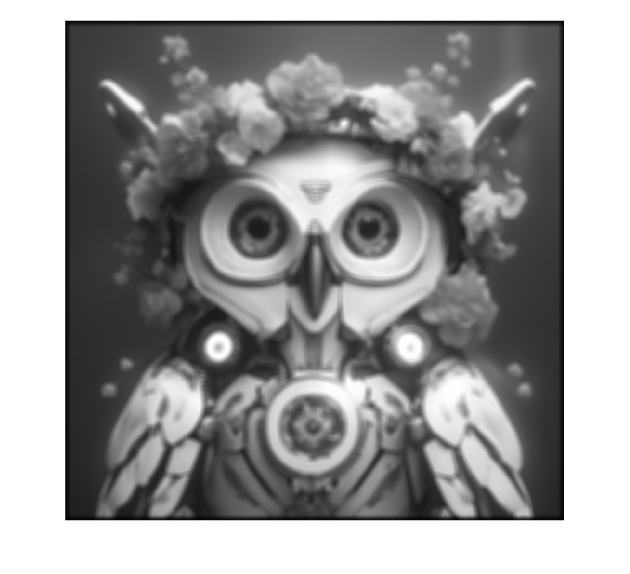


%imwrite(block_res_1_cov, "pic_2.jpg")
imshow(block_res_1_cov)